clc;
clear;
syms x;

a = 1;
b = 0;
c = 0;

%f(x) = 4 * x^2 - 2 * x - 4;
f =x;

P = 2; % Only works till P = 6  % Gauss points restriction
% P Order of Interpolation Function for element

% No of elements
e = 5;

% domain of X
x0 = 0;
xL = 1;

L = xL; % Length

[K_global_D_bc, Fv, S, X] = FEM_Processor(P, e, L, a, b, c, f);

% Get the handle of the command window
commandwindow;


% Prompt the user to input boundary conditions at x0
prompt_x0 = 'Enter the type of boundary condition at x0 (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        u0 = input('Enter the Dirichlet value u at x0: ');
    case 2
        Q0 = input('Enter the Neumann value AE*(du/dx) at x0: ');
    case 3
        K0 = input('Enter the spring constant K at x0: ');
        Del0 = input('Enter the spring displacement Del at x0: ');
    otherwise
        error('Invalid boundary condition type at x0');
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        uL = input('Enter the Dirichlet value u at xL: ');
    case 2
        P1 = input('Enter the Neumann value AE*(du/dx) at xL: ');
    case 3
        K1 = input('Enter the spring constant K at xL: ');
        Del1 = input('Enter the spring displacement Del at xL: ');
    otherwise
        error('Invalid boundary condition type at xL');
end


Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));


% For X0 left node we need to add correction factor
if exist('Q0', 'var') 
    Gv(1) = -Q0;   % Correction factor Added
end

if exist('K0', 'var') && exist('Del0', 'var')
    Sv(1) = -K0 * Del0;    % Correction factor Added
    K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
end



if exist('P1', 'var') 
    Gv(end) = P1;
end

if exist('K1', 'var') && exist('Del1', 'var')
    Sv(end) = K1 * Del1;  
    K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
end

RHS = Fv + Gv + Sv;


% Handle boundary conditions at x0
if exist('u0', 'var') 
    K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
    RHS(1) = u0;  % RHS of equation
end

% Handle boundary conditions at xL
if exist('uL', 'var') 
    K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
    RHS(end) = uL;  % RHS of equation
end  

K_global_D_bc

K_global_D_bc =     1.0000         0         0         0         0         0         0         0         0         0         0
  -13.3333   26.6667  -13.3333         0         0         0         0         0         0         0         0
    1.6667  -13.3333   23.3333  -13.3333    1.6667         0         0         0         0         0         0
         0         0  -13.3333   26.6667  -13.3333         0         0         0         0         0         0
         0         0    1.6667  -13.3333   23.3333  -13.3333    1.6667         0         0         0         0
         0         0         0         0  -13.3333   26.6667  -13.3333         0         0         0         0
         0         0         0         0    1.6667  -13.3333   23.3333  -13.3333    1.6667         0         0
         0         0         0         0         0         0  -13.3333   26.6667  -13.3333         0         0
         0         0         0         0         0         0    1.6667  -13.3333   23.3333  -13.

RHS

$$RHS = \left(\begin{array}{c} -1\\ -\frac{1}{75}\\ -\frac{1}{75}\\ -\frac{1}{25}\\ -\frac{2}{75}\\ -\frac{1}{15}\\ -\frac{1}{25}\\ -\frac{7}{75}\\ -\frac{4}{75}\\ -\frac{3}{25}\\ 2 \end{array}\right)$$


%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc \ RHS);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point       u   
    ___________    _______

          0             -1
        0.1        -0.7165
        0.2         -0.432
        0.3        -0.1455
        0.4          0.144
        0.5         0.4375
        0.6          0.736
        0.7         1.0405
        0.8          1.352
        0.9         1.6715
          1              2



disp("-------------------------------------------------------------")

-------------------------------------------------------------


syms x  u_e(x)
%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

Value1 = -1;
Value2 = 2;

d_ue(x)= diff(u_e,x);

ic1 = u_e(0) == Value1;
%ic1 = d_ue(0) == Value1;


ic2=u_e(1) == Value2;
%ic2 = d_ue(1) == Value2;

u_exact = dsolve(deqn,[ic1 ic2]);
exact_sol_f = u_exact

$$exact\_sol\_f = \frac{x^{3}}{6}+\frac{17\,x}{6}-1$$

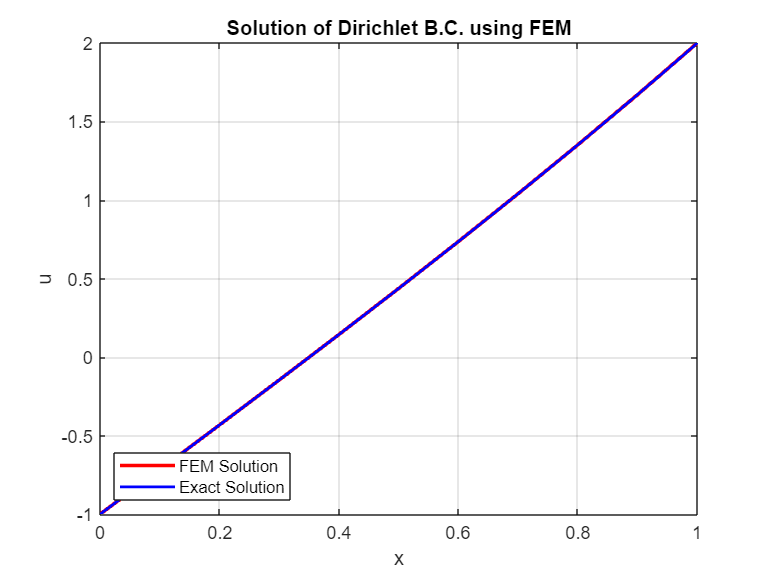

%----------------------------------------------------------------------------------


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;